close all; clear; clc;

# 90% ALL data collected data test 

**filename**: PercentAll_20180628.mlx

**keywords:** 

**file created by:** {20180629, Edmonds}

**last updated on:** {20180701}

**primary purpose:** EXPERIMENTAL SCRIPT. 

This script estimates system reaction time and acceleration. Because this is experimental, I don't think it should be used as verified data, but I would like to run this test on all the motors to compare to each other. 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** Rotational Speed was calculated in RPM, need to convert to rad/sec

Don't think I tore the load cell or voltage before running tests

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002285947263;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the "servo" column was deleted beforehand

load('PercentAll.mat');
time = PercentAll(:,1);          % [sec]
ESC_us = PercentAll(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = PercentAll(:,3);             % [ft.lbf]
T = PercentAll(:,4);             % [lbf]
Input_V = PercentAll(:,5);       % [Volts]
Input_A = PercentAll(:,6);       % [Amps]
rot_speed_RPM = PercentAll(:,7); % [rad/sec]
% Convert RPM to rad/sec
rot_speed = rot_speed_RPM .* (pi/30);

P_in_W = PercentAll(:,8);        % [Watts]
P_out_W = PercentAll(:,9);        % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = PercentAll(:,10);    % [%]
Prop_Eff = PercentAll(:,11);     % [lbf/Watts]
Overall_Eff = PercentAll(:,12);  % [lbf/Watts]  
Motor_Temp = PercentAll(:,13);   % [F]
Settling_time = PercentAll(:,14); % [s]
Max_Acc = PercentAll(:,15);      % [RPM]

## Thrust, Power, and Torque Coefficents

[C_T] = Thrust_Coefficient(T,p,area,rot_speed,radius);
[C_P] = Power_Coefficient(P_out,p,area,rot_speed,radius);
[C_Q] = Torque_Coefficient(Q,p,area,rot_speed,radius);

## Plots

{This is the section for generating output tables, plots, etc.}

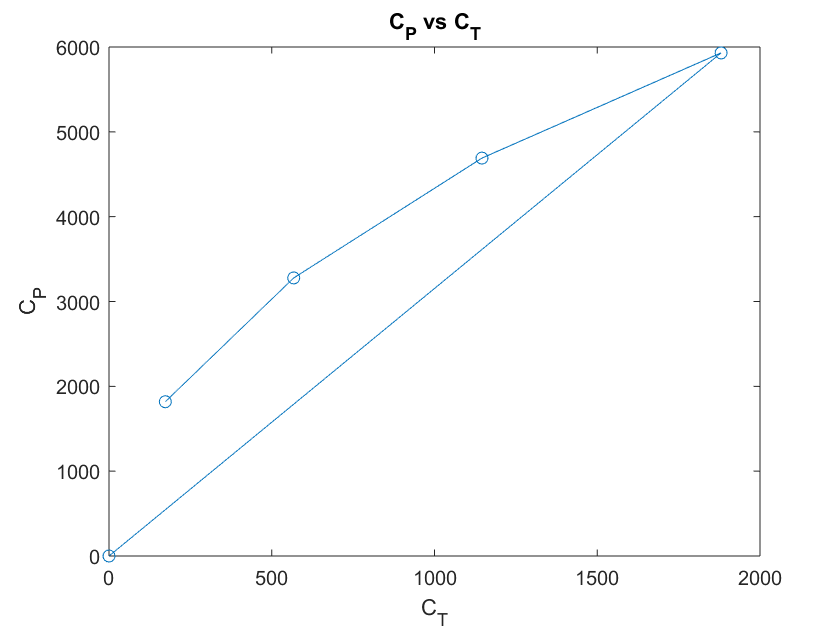




figure(1)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

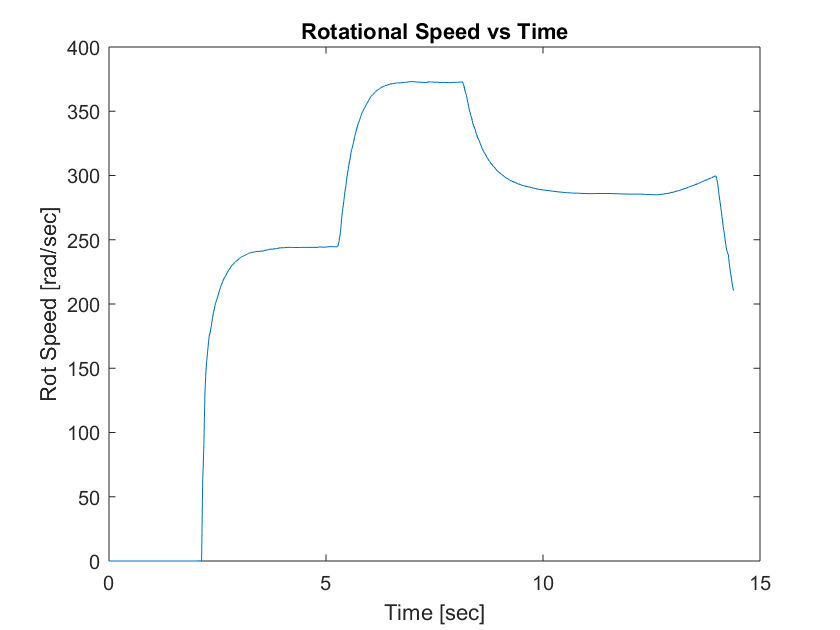

figure(2)
plot(time, rot_speed);
title('Rotational Speed vs Time'); xlabel('Time [sec]'); ylabel('Rot Speed [rad/sec]')

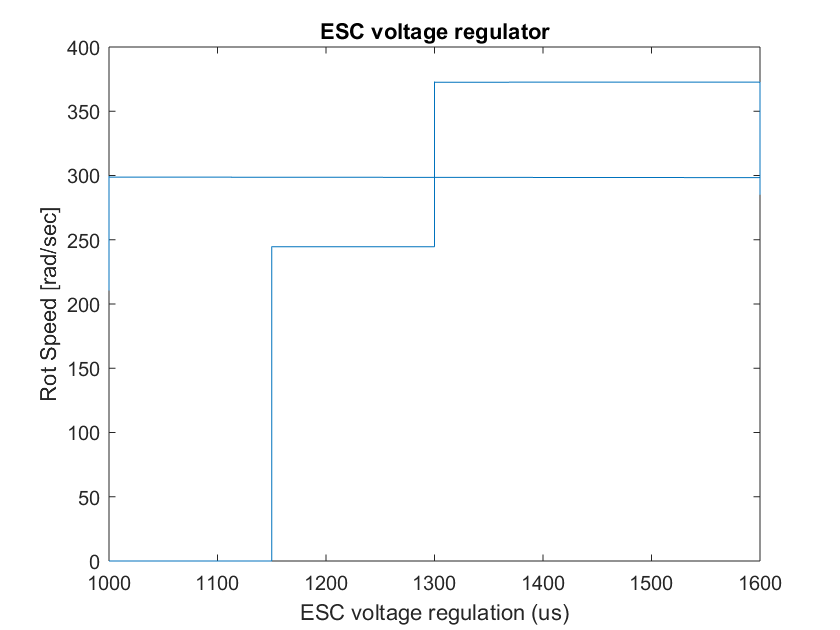

figure(3)
plot(ESC_us, rot_speed);
title('ESC voltage regulator'); xlabel('ESC voltage regulation (us)'); ylabel('Rot Speed [rad/sec]')

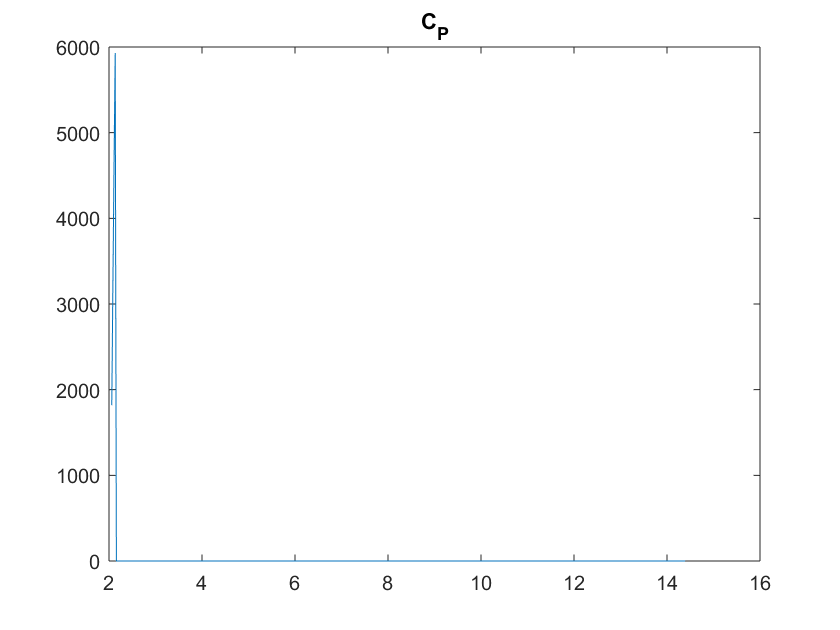





figure(4)
plot(time, C_P);
title('C_P');

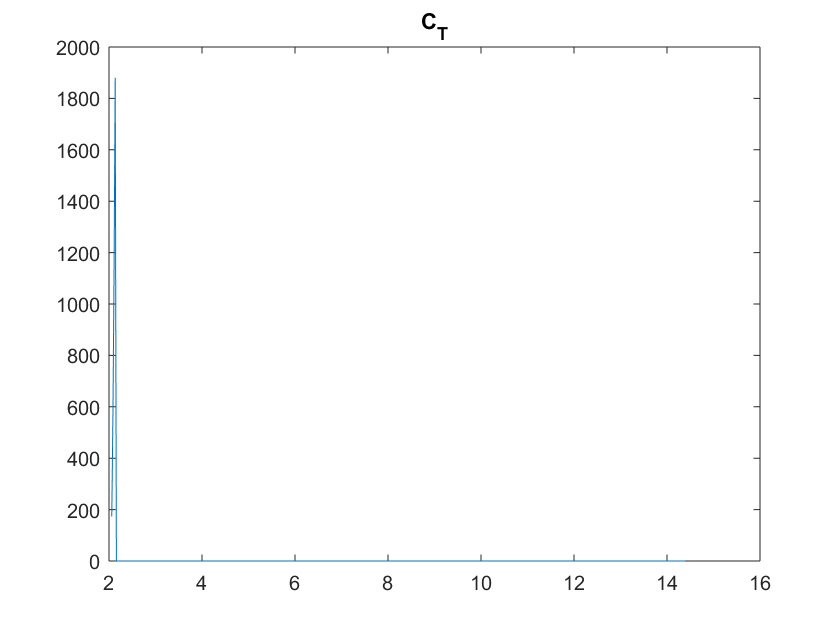


figure(5)
plot(time, C_T);
title('C_T');

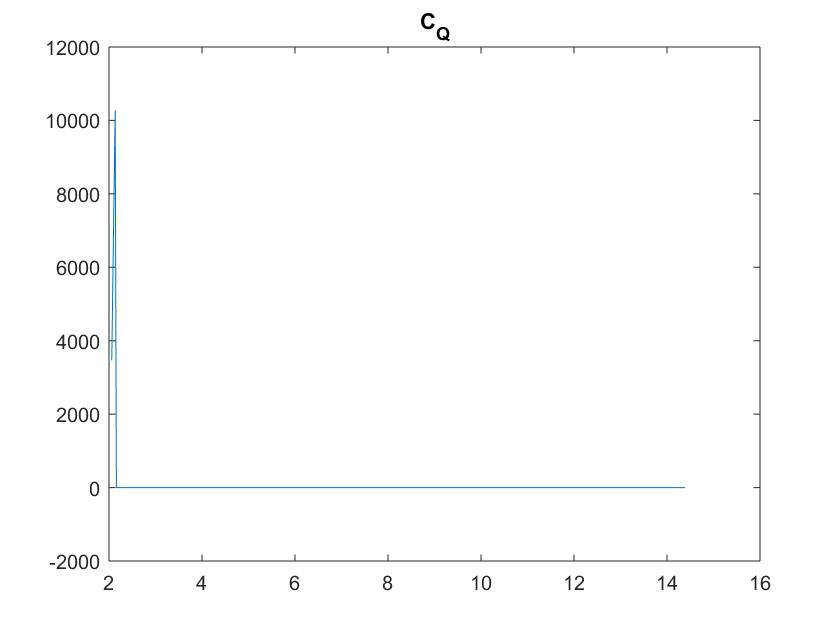


figure(6)
plot(time, C_Q);
title('C_Q');

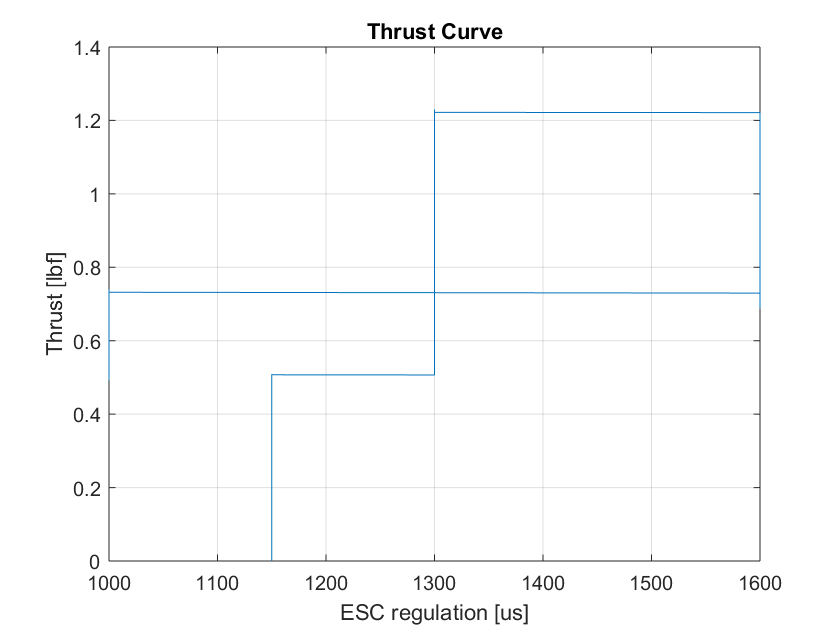

figure(7)
plot(ESC_us, T);
title('Thrust Curve'); xlabel('ESC regulation [us]'); ylabel('Thrust [lbf]'); 
grid('on'); ylim([0,1.4]);

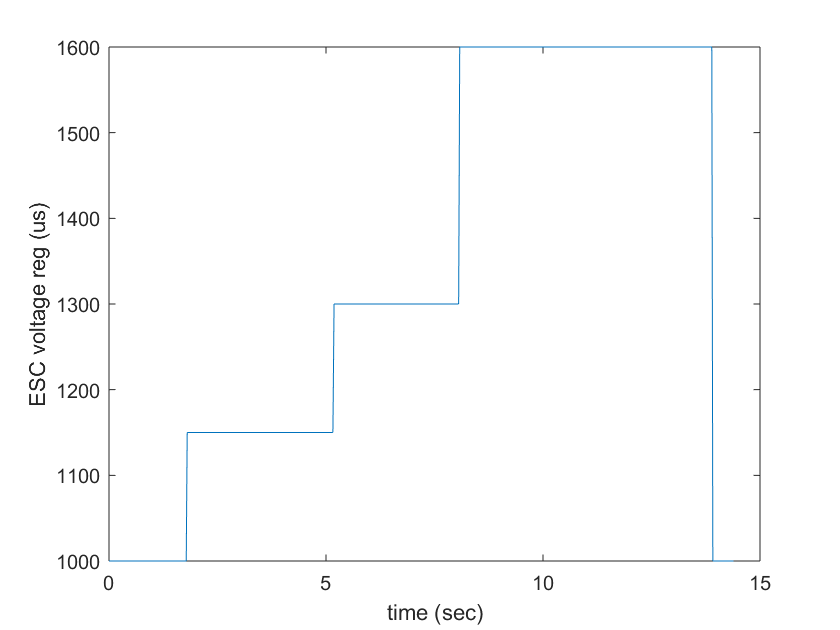






figure(8)
plot(time, ESC_us); xlabel('time (sec)'); ylabel('ESC voltage reg (us)')

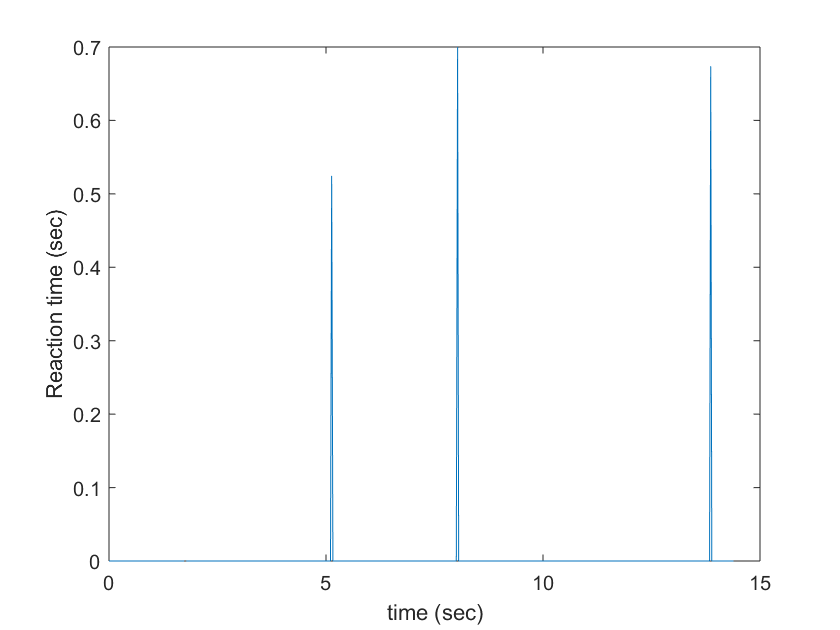


figure(9)
plot(time, Settling_time); 
xlabel('time (sec)'); ylabel('Reaction time (sec)')

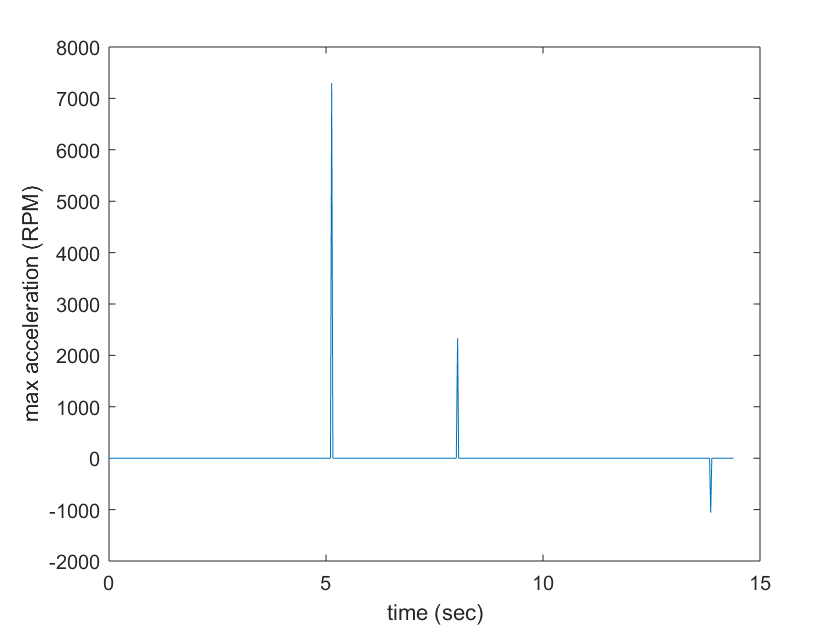



figure(10)
plot(time, Max_Acc);
xlabel('time (sec)'); ylabel('max acceleration (RPM)')

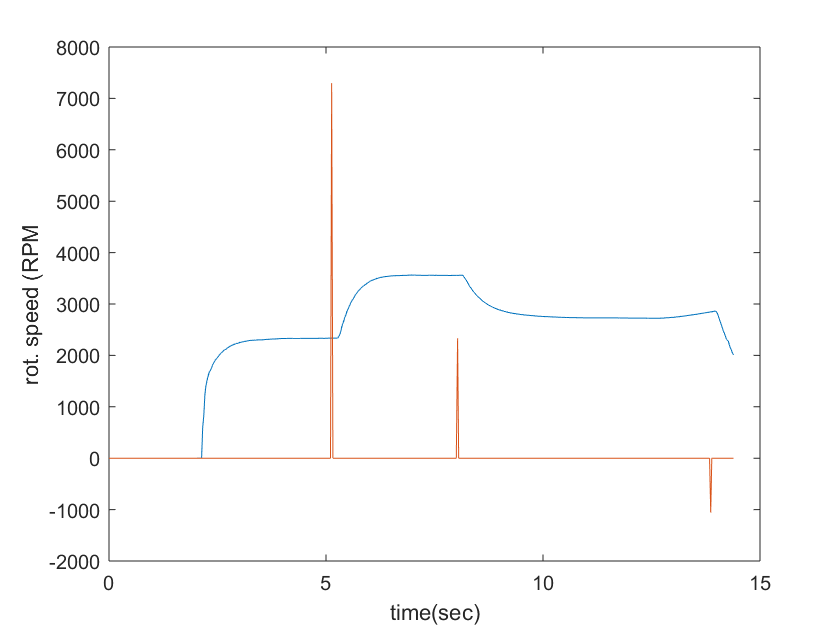

figure(11)
plot(time, rot_speed_RPM, time, Max_Acc);
xlabel('time(sec)'); ylabel('rot. speed (RPM');